In this lab we try to modelise a stochastic non-linear model. We assume the disturbances F3 and F4 to be stochastic but piecewise constant (normally distributed).

%--------------------------------------------------------
% Parameters
%--------------------------------------------------------
a1 = 1.2272; %[cm2] Area of outlet pipe 1
a2 = 1.2272;
a3 = 1.2272;
a4 = 1.2272;

A1 = 380.1327; %[cm2] Cross sectional area of tank 1
A2 = 380.1327; %[cm2] Cross sectional area of tank 2
A3 = 380.1327; %[cm2] Cross sectional area of tank 3
A4 = 380.1327; %[cm2] Cross sectional area of tank 4

gamma1 = 0.45; % Flow distribution constant. Valve 1
gamma2 = 0.40; % Flow distribution constant. Valve 2
g = 981;       %[cm/s2] The acceleration of gravity
rho = 1.00;    %[g/cm3] Density of water

p = [a1;a2;a3;a4; A1;A2;A3;A4; gamma1; gamma2; g; rho];


%-------------------------------------------------------
% System equations
%-------------------------------------------------------
function xdot = FourTankSystem(t,x,u,p)
% FOURTANKSYSTEM Model dx/dt = f(t,x,u,p) for 4-tank system

 m = x; % Mass of liquid in each tank [g]
 F = u; % Flow rates in pumps [cm3/s]
 a = p(1:4,1); % Pipe cross sectional areas [cm2]
 A = p(5:8,1); % Tank cross sectional areas [cm2]
 gamma = p(9:10,1); % Valve positions [-]
 g = p(11,1);   % Acceleration of gravity [cm/s2]
 rho = p(12,1); % Density of water [g/cm3]

 % Inflows
 qin = zeros(4,1);
 qin(1,1) = gamma(1)*F(1);     % Valve 1 to tank 1 [cm3/s]
 qin(2,1) = gamma(2)*F(2);     % Valve 2 to tank 2 [cm3/s]
 qin(3,1) = (1-gamma(2))*F(2); % Valve 2 to tank 3 [cm3/s]
 qin(4,1) = (1-gamma(1))*F(1); % Valve 1 to tank 4 [cm3/s]
 
 % % Outflows
 h = m./(rho*A);         % Liquid level in each tank [cm]
 qout = a.*sqrt(2*g*h);  % Outflow from each tank [cm3/s]

 % Differential equations, mass balances
 xdot = zeros(4,1);
 xdot(1,1) = rho*(qin(1,1)+qout(3,1)-qout(1,1)); % Tank 1
 xdot(2,1) = rho*(qin(2,1)+qout(4,1)-qout(2,1)); % Tank 2
 xdot(3,1) = rho*(qin(3,1)-qout(3,1));  % Tank 3
 xdot(4,1) = rho*(qin(4,1)-qout(4,1));  % Tank 4
end

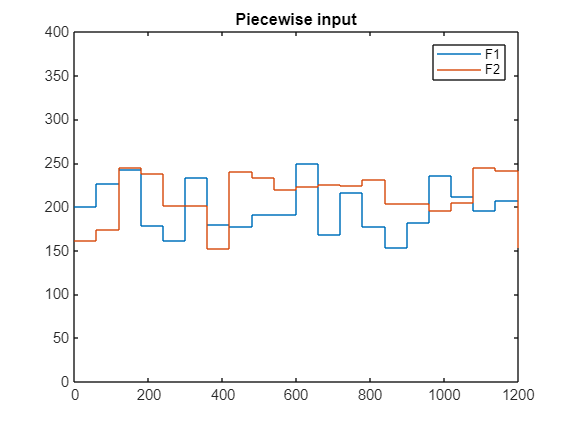

%-------------------------------------------------------
% Simulation scenario
%-------------------------------------------------------
t0 = 0.0;   % [s] Initial time
tf = 20*60; % [s] Final time
m10 = 0.0;  % [g] Liquid mass in tank 1 at time t0
m20 = 0.0;
m30 = 0.0;
m40 = 0.0;
F1 = 200;   % [cm3/s] Flow rate from pump 1
F2 = 200;

x0 = [m10; m20; m30; m40];
u = [F1; F2];

%-------------------------------------------------------
% Determinsitic disturbances on control (piecewise constant)
%-------------------------------------------------------
Ts = 10; % [s] Sample Time
t = [t0:Ts:tf]; % [s] Sample instants
n = length(t);
k = 6; % nbr of time sample over which the control command is constant
u = repmat(u', n, 1);
d = [randi([-50, 50], ceil((n+1)/k), 1), randi([-50, 50], ceil((n+1)/k), 1)];
d = repelem(d, k, 1);
d = d(1:n, :);

u = u+d;

stairs(t,u)
ylim([0,400])
legend("F1", "F2")
title("Piecewise input")

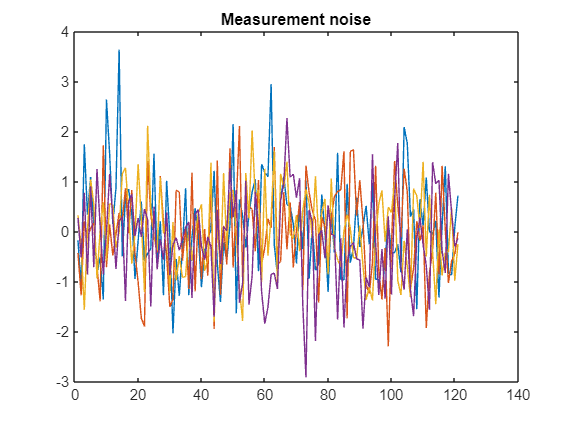


%-------------------------------------------------------
% Measurement noise
%-------------------------------------------------------
R = eye(4);
Lr = chol(R,'lower');
v = Lr*randn(4,n);
v = v';
plot(v)
title("Measurement noise")

%-------------------------------------------------------
% Compute the solution / Simulate
%-----------------------------------------------------
x = zeros(n,4);
y = zeros(n,4);
z = zeros(n,4);
X = zeros(0,4);
T = zeros(0,1);
A = p(5:8,1);
a = p(1:4,1);

x(1,:) = x0;

for k = 1:n-1
    [Tk,Xk] = ode15s(@FourTankSystem,[t(k) t(k+1)],x(k,:),[],u(k,:),p);
    x(k,:) = Xk(end,:);
    Tk = [Tk; Tk];
    Xk = [Xk; Xk];
    y(k,:) = x(k,:)./(rho*A') + v(k,:); % Sensor function
    z(k,:) = x(k,:)./(rho*A');          % Output function
    % 
end
k = n;
y(k,:) = x(k,:)./(rho*A') + v(k,:); % Sensor function
z(k,:) = x(k,:)./(rho*A');          % Output function

% Compute the flows out of each tank
Qout = zeros(n,4);
for i=1:n
    Qout(i,:) = a.*sqrt(2*g*z(i,:)');
end

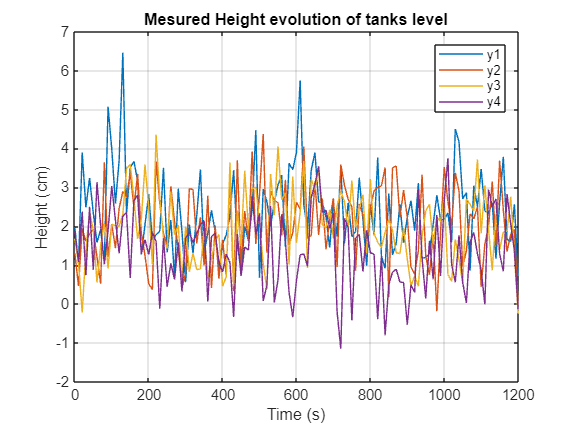

plot(t, y)
xlabel('Time (s)');
ylabel('Height (cm)');
title('Mesured Height evolution of tanks level');
legend('y1', 'y2', 'y3', 'y4');
grid on;

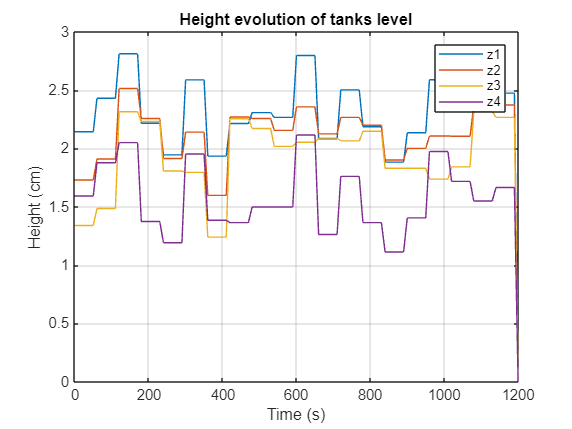


plot(t, z)
xlabel('Time (s)');
ylabel('Height (cm)');
title('Height evolution of tanks level');
legend('z1', 'z2', 'z3', 'z4');
grid on;

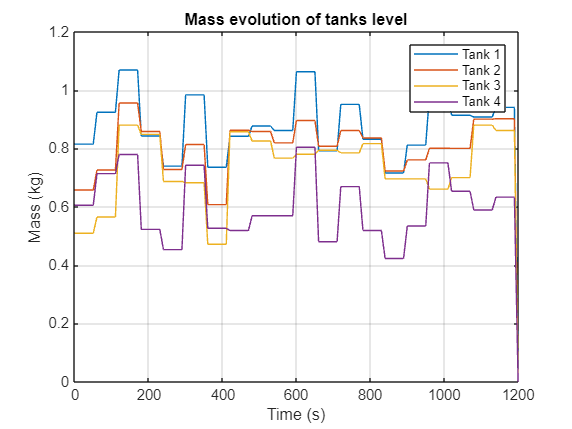


plot(t, x/1000)
xlabel('Time (s)');
ylabel('Mass (kg)');
title('Mass evolution of tanks level');
legend('Tank 1', 'Tank 2', 'Tank 3', 'Tank 4');
grid on;

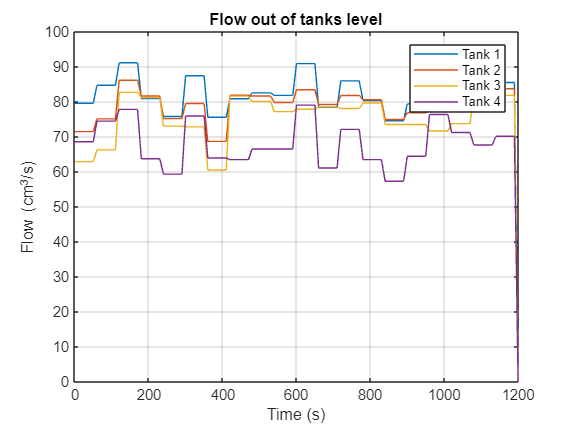


plot(t, Qout)
xlabel('Time (s)');
ylabel('Flow (cm^3/s)');
title('Flow out of tanks level');
legend('Tank 1', 'Tank 2', 'Tank 3', 'Tank 4');
grid on;